# Práctica 8. Métodos adaptativos para EDOs

El objetivo de esta práctica es estudiar métodos adaptativos monopaso para la ecuación


$$\mathrm{(PVI)} \qquad \begin{cases}
\frac{d\mathbf{u}}{dt} (t) = \mathbf f (t, \mathbf u (t)) & t \in [t_0, T], \\
\mathbf u(t_0) = \mathbf u_0 
\end{cases}$$


## 1 Método de Runge-Kutta encajados

En esta práctica utilizaremos los siguientes métodos: 

Método de Euler explícito, que se puede escribir como método de Runge-Kutta


$$\mathbf U_{i+1} = \mathbf U_i + h \mathbf F_1$$


donde

$\mathbf F_1 = \mathbf f(t_i, \mathbf U_i)$.

Se tiene el tablero de Butcher

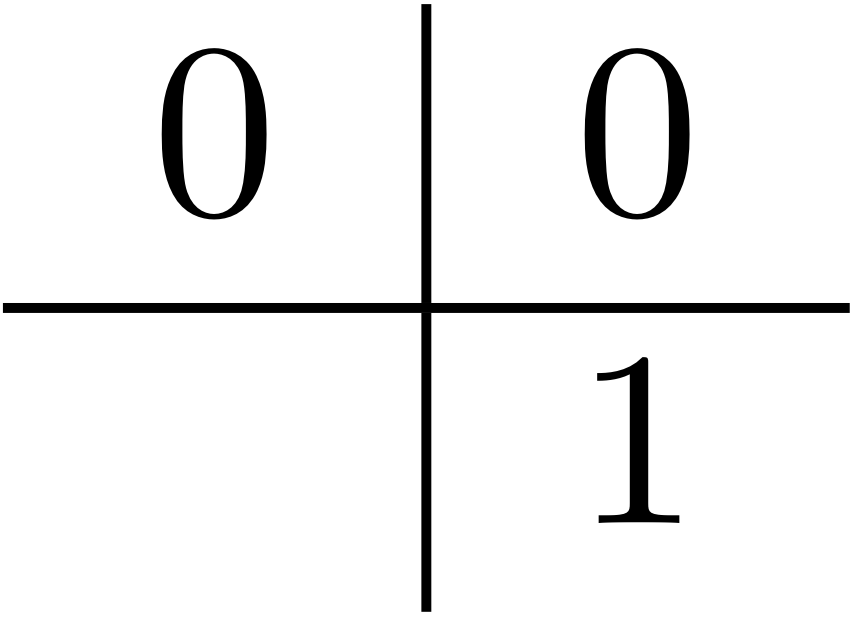

Otro método de Runge-Kutta explícito es el método de Heun (también llamado de Euler mejorado) de orden 2


$$\mathbf U_{i+1} = \mathbf U_i + h \left(  \frac 1 2 \mathbf F_1 + \frac 1 2 \mathbf F_2   \right)$$


donde


$$\mathbf F_1=\mathbf f(t_i, \mathbf U_i)$$



$$\mathbf F_2 = \mathbf f (t_i + h , \mathbf U_i + h \mathbf F_1)$$


es decir, con tablero

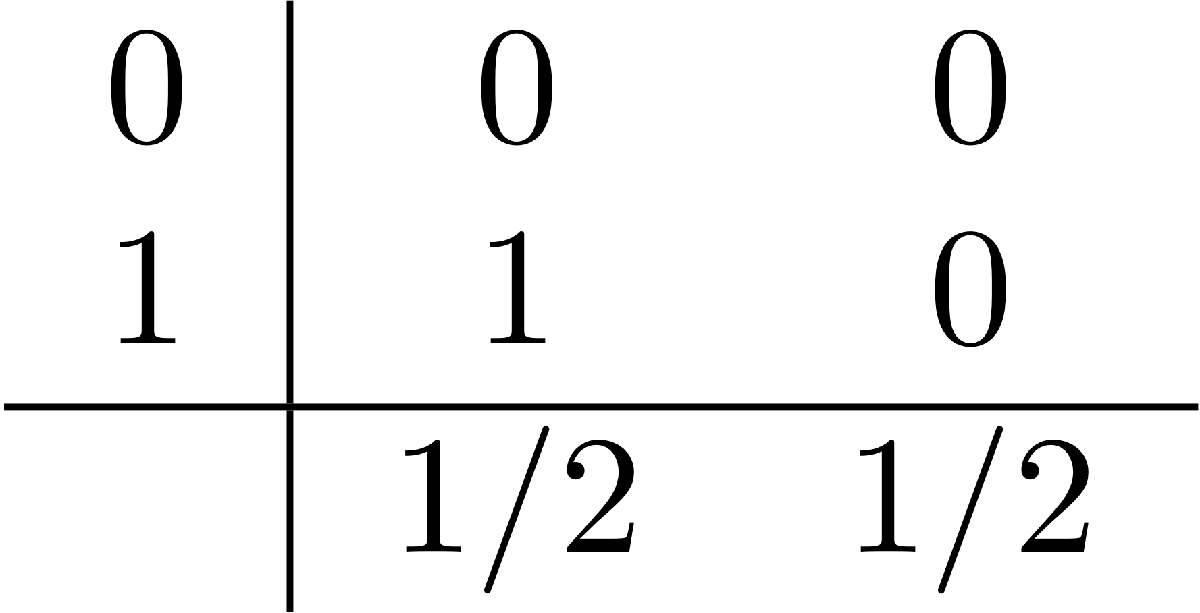

Obsérvese que ambos métodos comparten $\mathbf F_1$.

El tablero de Butcher de ambos métodos encajados es

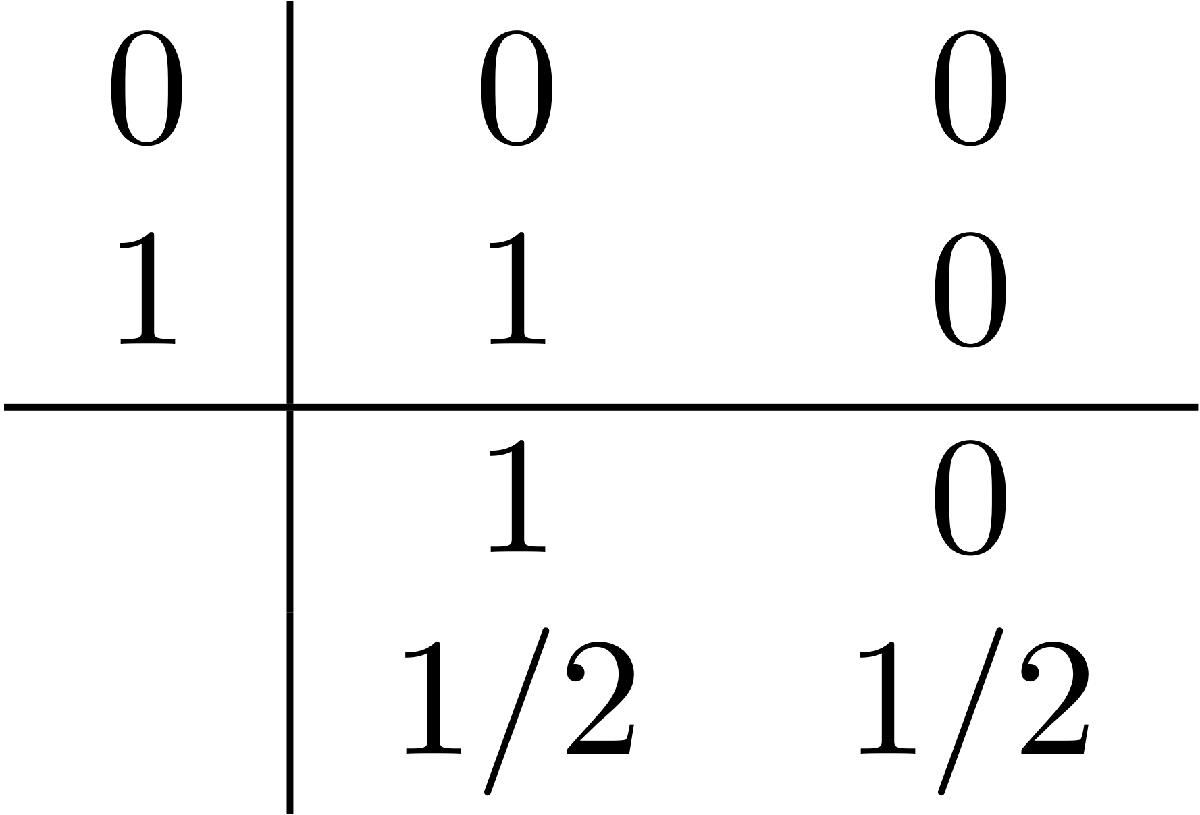 

### 1. Implementación

En el apéndice A1 implementar una función que que implemente el método de Runge-Kutta encajado anterior y responda a la sintaxis

`[t,U,tr,hr] = RK12(f,u0,interv,param)`

donde `tr,hr `representan los pasos rechazados, donde `param `es un vector con los parámetros

`param = [h_init, fac, facmax, facmin, Atol, Rtol, max_iter]`

Para los ejemplos siguientes tomaremos

`h_init = 1e-3;`

`fac = 0.8;`

`facmax = 1.5; `

`facmin = 0.5; `

`Atol = 1e-2*ones(1,n);`

`Rtol = 1e-2*ones(1,n);`

`max_iter = 1000`

param = [ 1e-3, 0.8, 1.5, 0.5, 1e-3, 1e-3, 1000];
%Orden de Euler explicito 1 (p)
%Orden de Heun (p_gorro)
%Por tanto q=1

(Nota: para conseguir mejores resultados, al terminar la práctica, se utilizar 

`param = [ 1e-3, 0.8, 1.5, 0.5, 1e-3, 1e-3, 10000]`)

### 2. Ecuaciones con distintos ritmos

Aplicar el método sobre la EDO


$$u_1'(t) = 1+u_1^2u_2-4u_1\\
u_2'(t) = 3u_1-u_1^2u_2 \\
u_1(0) = 1.5\\
u_2(0) = 3$$


Representar la solución y el paso utilizado en gráficas separadas. Estudiar en qué regiones se hace el paso pequeño.

Con los parámetros utilizados ¿se rechazan pasos en esta ecuación? ¿por qué?

u1_0=1.5;
u2_0=3;
interv=[0,5];
f1=@(u1,u2)[1+u1^2*u2-4*u1];
f2=@(u1,u2)[3*u1-u1^2*u2];
for k=1:1000
    param(1,7)=k;
    clear h
   [t1,U1,tr1,hr1] = RK12(f1,u1_0,interv,param);
   [t2,U2,tr2,hr2] = RK12(f2,u2_0,interv,param);
end

### 3. Detectar blow-up

Probar el método sobre la ecuación


$$u'(t) = u(t)^2\\
u(0) = 1$$


de solución explícita


$$u(t) = (1-t)^{-1}$$


Indicar al método que emplee el intervalo $[0,2]$. Comparar el resultado numérico con el teórico. Representar el paso y también los pasos rechazados. ¿Qué tal se detecta la asíntota horizontal?

Con los parámetros utilizados ¿se rechazan pasos en esta ecuación? ¿por qué?

% clear all
% param = [ 1e-3, 0.8, 1.5, 0.5, 1e-3, 1e-3, 10000];
% f=@(u)[u^2];
% u0=1;
% interv=[0,2];
% [t,U,tr,hr] = RK12(f,u0,interv,param)

## Apéndice

### A1. Método de Runge-Kutta Euler explícito--Heun

function [t,U,tr,hr] = RK12(f,u0,interv,param) 
    h = param(1,1);
    fac = param(1,2);
    facmax = param(1,3); 
    facmin = param(1,4); 
    Atol = param(1,5);
    Rtol = param(1,6);
    max_iter = param(1,7);
    t(1)=interv(1);
    u(1)=u0;
    U(1)=u0;
    hr=[];
    tr=[];
    i=1;
    iter=1;
    while t(i)<interv(2)
        hr=[hr h];
        t(i+1)=t(i)+h; 
        tr=[tr t(i+1)];
        %Calculamos u con los dos metodos RK encajados
        %RK Euler explicito
        U(i+1)=u(i)+h*f(t(i),u(i));
        %RK Heun
        F1=f(t(i),u(i));
        F2=f(t(i)+h,u(i)+h*F1);
        U_gorro(i+1)=u(i)+h*((1/2)*F1+(1/2)*F2);
        suma=0;
        for j=1:length(u)
            sc(j)=Atol+max(abs(u(j)),abs(U(j)))*Rtol;
            suma=suma+((U(j)-U_gorro(j))/sc(j))^2;
        end
        err=sqrt(suma/length(u));
        maximo=max(facmin,fac*(1/err)^(1/2));
        h=min(facmax,maximo);
        if err<=1
            i=i+1;
            u(i)=U(i);
            hr(length(hr))=[];
            tr(length(tr))=[];
        end
        iter=iter+1;
        if  iter>max_iter
            break 
        end
    end
end